clear; close all;
g = 9.8;
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;

A = [0 1 0 0 0 0;
    0 0 ((-g*m1)/M) 0 ((-g*m2)/M) 0;
    0 0 0 1 0 0;
    0 0 ((-g*(M+m1))/(M*l1)) 0 -((g*m2)/(M*l1)) 0;
    0 0 0 0 0 1;
    0 0 ((-g*m1)/(M*l2)) 0 ((-g*(M+m2))/(M*l2)) 0 ];

B = [0;
    (1/M);
    0;
    (1/(M*l1));
    0;
    (1/(M*l2))];

C = eye(6);
D = 0;

Q = 100*eye(6);
R = 0.001;

For output vector x(t), C is

disp("Output vector is x(t), C:");

Output vector is x(t), C:


C1 = [1 0 0 0 0 0];
disp(C1);

     1     0     0     0     0     0



For output vector {x(t),$\left.\theta 1\left(t\right),\theta 2\left(t\right)\right\rbrace$, C is

disp("Output vector is x(t),theta1(t), theta2(t)");

Output vector is x(t),theta1(t), theta2(t)


C2 = [1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];
disp(C2);

     1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0



For output vector {x(t),$\left.\theta 2\left(t\right)\right\rbrace$, C is

disp("Output vector is x(t),theta2(t)");

Output vector is x(t),theta2(t)


C3 = [1 0 0 0 0 0;
      0 0 0 0 1 0];
disp(C3);

     1     0     0     0     0     0
     0     0     0     0     1     0



For output vector {$\left.\theta 1\left(t\right),\theta 2\left(t\right)\right\rbrace$, C is

disp("Output vector is theta1(t),theta2(t)");

Output vector is theta1(t),theta2(t)


C4 = [0 0 1 0 0 0;
      0 0 0 0 1 0];
disp(C4);

     0     0     1     0     0     0
     0     0     0     0     1     0



Define the observability matrices for the above 4 outputs

AO1 = [C1.' A.'*C1.' (A.')^2*C1.' (A.')^3*C1.' (A.')^4*C1.' (A.')^5*C1.'];
AO2 = [C2.' A.'*C2.' (A.')^2*C2.' (A.')^3*C2.' (A.')^4*C2.' (A.')^5*C2.'];
AO3 = [C3.' A.'*C3.' (A.')^2*C3.' (A.')^3*C3.' (A.')^4*C3.' (A.')^5*C3.'];
AO4 = [C4.' A.'*C4.' (A.')^2*C4.' (A.')^3*C4.' (A.')^4*C4.' (A.')^5*C4.'];

rank1 = rank(AO1);
rank2 = rank(AO2);
rank3 = rank(AO3);
rank4 = rank(AO4);

If the observability matrix is of full rank, then the system is observable.

disp("Rank of A01:");

Rank of A01:


disp(rank1);

     6



disp("Rank of A02:");

Rank of A02:


disp(rank2);

     6



disp("Rank of A03:");

Rank of A03:


disp(rank3);

     6



disp("Rank of A04:");

Rank of A04:


disp(rank4);

     4



For outputs x(t),{x(t),$\left.\theta 1\left(t\right),\theta 2\left(t\right)\right\rbrace$,{x(t),$\left.\theta 2\left(t\right)\right\rbrace$, the system is observable.

[K,~,~] = lqr(A, B, Q, R);

%Assume the poles such that they are in negative half plane
observer_poles = [-1,-2,-3,-4,-5,-6];
% Choose the observer gain matrix L
L1 = place(A', C1', observer_poles);
disp(L1);

   1.0e+03 *

    0.0210    0.1734   -2.9329    0.0792    2.2176   -1.4496



L2 = place(A', C2', observer_poles);
disp(L2);

    8.5631   17.5219   -0.9140   -4.1173    0.0000    0.0000
   -0.8851   -4.9474    9.4369   20.9390   -0.0000   -0.0980
    0.0000   -0.9800   -0.0000   -0.0491    3.0000    0.9220



L3 = place(A', C3', observer_poles);
disp(L3);

   13.0743   56.2564  -89.1734  -20.0624    0.3520    3.4792
   -0.8243   -8.4778   19.7841   10.9530    7.9257   13.2136



For first observable system:

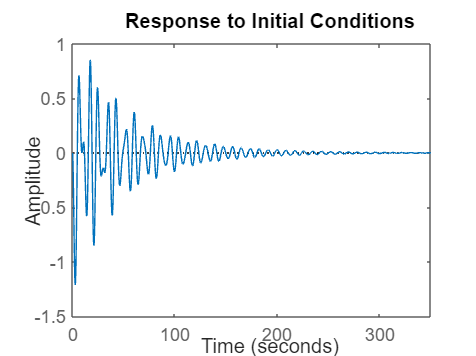

A_c1 = [(A-B*K) B*K ; zeros(size(A)) (A-(L1'*C1))];
B_c1 = [B;B];
C_c1 = [C1 zeros(size(C1))];

sys1 = ss(A_c1,B_c1,C_c1,D);
x_0 = [0;0;0.5;0;0.6;0;0;0;0;0;0;0];
initial(sys1,x_0);

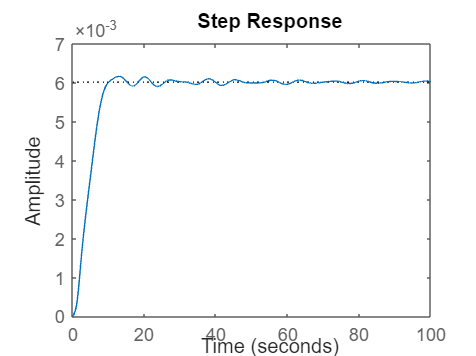

step(sys1);

For second observable system:

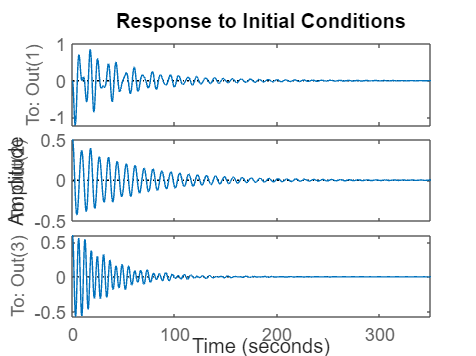

A_c2 = [(A-B*K) B*K ; zeros(size(A)) (A-(L2'*C2))];
B_c2 = [B;B];
C_c2 = [C2 zeros(size(C2))];

sys2 = ss(A_c2,B_c2,C_c2,D);
initial(sys2,x_0);

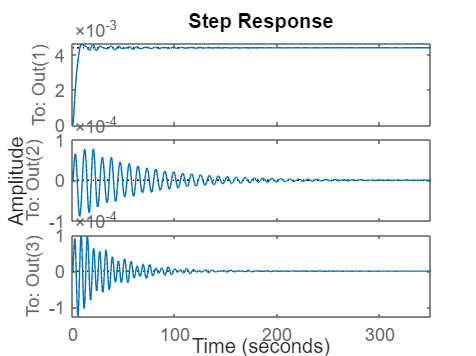

step(sys2);

For third observable system:

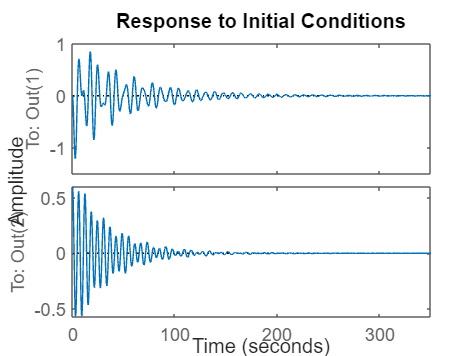

A_c3 = [(A-B*K) B*K ; zeros(size(A)) (A-(L3'*C3))];
B_c3 = [B;B];
C_c3 = [C3 zeros(size(C3))];

sys3 = ss(A_c3,B_c3,C_c3,D);
initial(sys3,x_0);

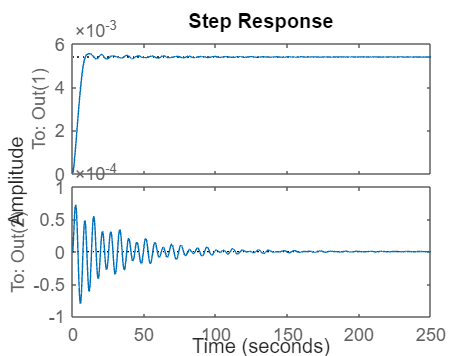

step(sys3);